# **MATLAB ACTIVITY BOOK FOR THIRD SEMESTER**

# `Activity-1: Fourier Series`

**Definition:**** Fourier series of a piecewise continuous function **$f\left(x\right)\;$**in the interval **$\left\lbrack a,a+2l\right\rbrack$** is given by:**

$F\left\lbrace f\left(x\right)\right\rbrace =\frac{a_0 }{2}+\sum_{n=1}^{\infty } a_n \cos \left(\frac{n\pi x}{l}\right)+\sum_{n=1}^{\infty } b_n \sin \left(\frac{n\pi x}{l}\right)$ **where,**

#### 
$$a_0 =\frac{1}{l}\int_a^{a+2l} f\left(x\right)\textrm{dx}\;\;\;,\;\;\;\;a_n =\frac{1}{l}\int_a^{a+2l} f\left(x\right)\cos \left(\frac{n\pi x}{l}\right)\textrm{dx}\;\;\;,\;\;\;\;b_n =\frac{1}{l}\int_a^{a+2l} f\left(x\right)\sin \left(\frac{n\pi x}{l}\right)\textrm{dx}$$


**Question****: Write a matlab code to find the Fourier series of **$f\left(x\right)=e^x$** in the interval **$\left\lbrack -\pi ,\pi \right\rbrack$** upto 25 terms. Visualize by obtaining obtaining the graphs of both the function and the series on the same plot.**

clear all
syms x
a=-pi; %lower limit of the interval
b=pi; %upper limit of the interval
I=[a b];
l=(b-a)/2; % the value of l
y = exp(x);

%Construction of Fourier Series
a0 = vpa((1/l)*int(y,x,a,b),3); %Formula for a0
i = 25;
sum=0;
for n= 1:i
an = (1/l)*int(y*cos((n*pi*x)/l),x,I); %Formula for an
bn = (1/l)*int(y*sin((n*pi*x)/l),x,I); %Formula for bn
sum = sum + an*cos((n*pi*x)/l) + bn*sin((n*pi*x)/l);
end
F=vpa((a0/2)+sum,3) %Required Fourier Series
%Visualize by plotting
fplot(x,y,I)
grid on;
hold on;
fplot(x,F,I)
title('Fourier Series of a function')
legend('Function', 'Its Fourier Series')
hold off

### Excercises:

**1. Solve the problem manually and verify with the series obtained in the output for the first three terms.**

$$F = 1.47\,\cos\left(2.0\,x\right)+0.432\,\cos\left(4.0\,x\right)+0.113\,\cos\left(8.0\,x\right)+0.0286\,\cos\left(16.0\,x\right)-0.0254\,\cos\left(17.0\,x\right)-0.0897\,\cos\left(9.0\,x\right)+0.0226\,\cos\left(18.0\,x\right)-0.0203\,\cos\left(19.0\,x\right)-2.94\,\sin\left(2.0\,x\right)-1.73\,\sin\left(4.0\,x\right)-0.905\,\sin\left(8.0\,x\right)-0.458\,\sin\left(16.0\,x\right)-0.283\,\cos\left(5.0\,x\right)+0.0728\,\cos\left(10.0\,x\right)+0.0183\,\cos\left(20.0\,x\right)+0.431\,\sin\left(17.0\,x\right)-0.0166\,\cos\left(21.0\,x\right)+0.807\,\sin\left(9.0\,x\right)-0.407\,\sin\left(18.0\,x\right)-0.0603\,\cos\left(11.0\,x\right)+0.0152\,\cos\left(22.0\,x\right)+0.386\,\sin\left(19.0\,x\right)-0.0139\,\cos\left(23.0\,x\right)+1.41\,\sin\left(5.0\,x\right)-0.728\,\sin\left(10.0\,x\right)-0.367\,\sin\left(20.0\,x\right)-0.735\,\cos\left(3.0\,x\right)+0.199\,\cos\left(6.0\,x\right)+0.0507\,\cos\left(12.0\,x\right)+0.0127\,\cos\left(24.0\,x\right)+0.349\,\sin\left(21.0\,x\right)-0.0117\,\cos\left(25.0\,x\right)+0.663\,\sin\left(11.0\,x\right)-0.333\,\sin\left(22.0\,x\right)-0.0432\,\cos\left(13.0\,x\right)+0.319\,\sin\left(23.0\,x\right)+2.21\,\sin\left(3.0\,x\right)-1.19\,\sin\left(6.0\,x\right)-0.608\,\sin\left(12.0\,x\right)-0.306\,\sin\left(24.0\,x\right)-0.147\,\cos\left(7.0\,x\right)+0.0373\,\cos\left(14.0\,x\right)+0.294\,\sin\left(25.0\,x\right)+0.562\,\sin\left(13.0\,x\right)-0.0325\,\cos\left(15.0\,x\right)+1.03\,\sin\left(7.0\,x\right)-0.522\,\sin\left(14.0\,x\right)+0.488\,\sin\left(15.0\,x\right)-3.68\,\cos\left(x\right)+3.68\,\sin\left(x\right)+3.68$$

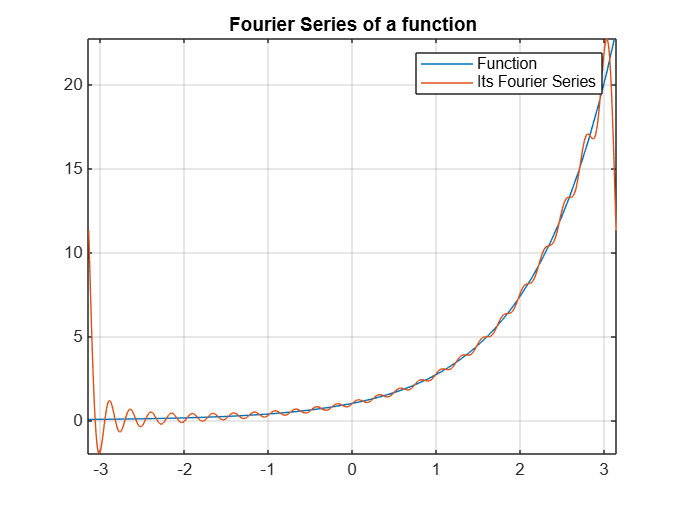

**2. Increase and decrease the value of '**$i$**' in the above code. What is your observation on the accuracy of the series on changing the value of '**$i$**' ?**

***Answer******: *****Increasing the value of i it increases the accuracy of the Fourier series approximation. However,diminishing returns occur after a certain point, as the additional terms contribute less to improving the accuracy.**

**3. Write a MaTlab code to obtain the Fourier series for the following functions and obtain the outputs and paste the graphs:**

**a) **$\cos \left(x\right)$** in the interval **$\left\lbrack -\pi ,\pi \right\rbrack$

**i) Why is the value of **$b_n$** zero in a?**

***Answer*****:   y=cos(x) , it is even function**

clear all
syms x
a = -pi; % Lower limit of the interval
b = pi;  % Upper limit of the interval
I = [a b]; % Interval
l = (b - a) / 2; % Value of l (half the interval length)

% Define the function
y = cos(x);

% Construction of Fourier Series
b0 = vpa((1/l) * int(y, x, a, b), 3); % Compute a0
disp('b0:');

b0:


disp(b0); % Display a0

$$0.0$$


i = 3; % Number of terms in the Fourier series
sum1 = 0;

for n = 1:i
    % Compute Fourier coefficients an and bn
    an = vpa((1/l) * int(y * cos((n * pi * x) / l), x, I), 3); % Compute an
    bn = vpa((1/l) * int(y * sin((n * pi * x) / l), x, I), 3); % Compute bn (should be zero for cos(x))
    
    % Add each term to the Fourier series
    sum1 = sum1 + an * cos((n * pi * x) / l) + bn * sin((n * pi * x) / l);
end

% Complete Fourier Series
F = vpa((a0 / 2) + sum1, 3); % Required Fourier Series

% Display the Fourier Series
disp('Fourier Series:');

Fourier Series:


disp(F);

$$1.0\,\cos\left(x\right)$$

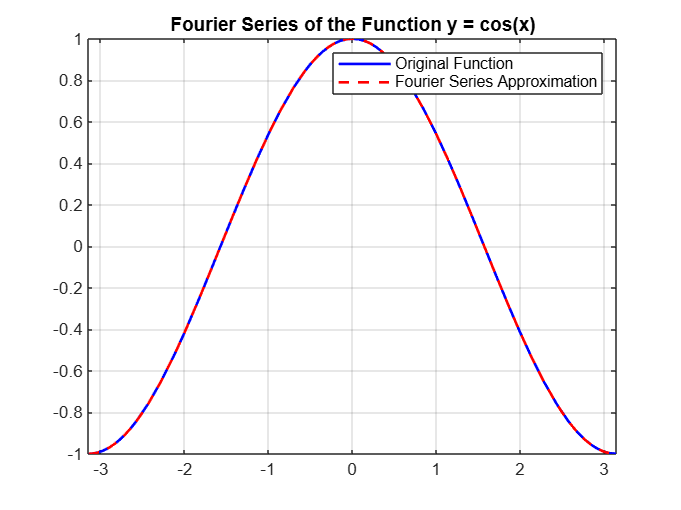


% Visualization by Plotting
fplot(y, I, 'b', 'LineWidth', 1.5); % Original function
hold on;
fplot(F, I, 'r--', 'LineWidth', 1.5); % Fourier series approximation
grid on;
title('Fourier Series of the Function y = cos(x)');
legend('Original Function', 'Fourier Series Approximation');
hold off;

**b) **$\sin \left(x\right)$** in the interval **$\left\lbrack -\pi ,\pi \right\rbrack$

**ii) Why is the value of **$a_n$** is zero in a?**

***Answer******:   *****y=sin(x), it is odd function.**

clear all
syms x
a = -pi; % Lower limit of the interval
b = pi;  % Upper limit of the interval
I = [a b]; % Interval
l = (b - a) / 2; % Value of l (half the interval length)

% Define the function
y = sin(x);

% Construction of Fourier Series
a0 = vpa((1/l) * int(y, x, a, b), 3); % Compute a0 (should be zero for sine)

a0:


disp('a0:');

$$0.0$$

disp(a0); % Display a0 (expected to be 0)

i = 3; % Number of terms in the Fourier series
sum1 = 0;

for n = 1:i
    % Compute Fourier coefficients an and bn
    an = vpa((1/l) * int(y * cos((n * pi * x) / l), x, I), 3); % Should be zero
    bn = vpa((1/l) * int(y * sin((n * pi * x) / l), x, I), 3); % Compute bn
    
    % Add each term to the Fourier series
    sum1 = sum1 + an * cos((n * pi * x) / l) + bn * sin((n * pi * x) / l);
end

% Complete Fourier Series
F = vpa((a0 / 2) + sum1, 3); % Required Fourier Series

% Display the Fourier Series

Fourier Series:


disp('Fourier Series:');

$$1.0\,\sin\left(x\right)$$

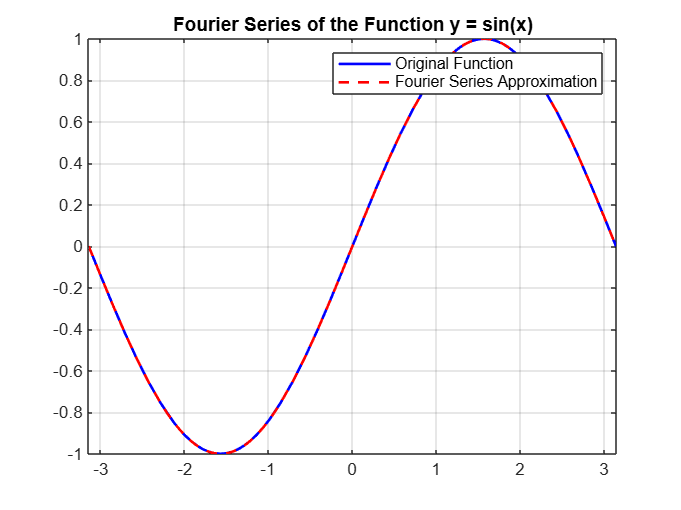

disp(F);

% Visualization by Plotting
fplot(y, I, 'b', 'LineWidth', 1.5); % Original function
hold on;
fplot(F, I, 'r--', 'LineWidth', 1.5); % Fourier series approximation
grid on;
title('Fourier Series of the Function y = sin(x)');
legend('Original Function', 'Fourier Series Approximation');

hold off;

**4. Obtain the outputs for the following functions and paste the graphs:**

**a) **$x\left(2\pi -x\right)$** in the interval **$\left\lbrack 0,2\pi \right\rbrack$**.**

clear all
syms x
a=0; %lower limit of the interval
b=2*pi; %upper limit of the interval
I=[a b];
l=(b-a)/2; % the value of l
y = x*(2*pi-x);
%Construction of Fourier Series
a0 = vpa((1/l)*int(y,x,a,b),3); %Formula for a0
5

ans = 5

i = 3;
sum1=0;
for n= 1:i
an = (1/l)*int(y*cos((n*pi*x)/l),x,I); %Formula for an
bn = (1/l)*int(y*sin((n*pi*x)/l),x,I); %Formula for bn
sum1 = sum1 + an*cos((n*pi*x)/l) + bn*sin((n*pi*x)/l);
end
F=vpa((a0/2)+sum1,3) %Required Fourier Series

$$F = 6.58-0.444\,\cos\left(3.0\,x\right)-4.0\,\cos\left(x\right)-1.0\,\cos\left(2.0\,x\right)$$

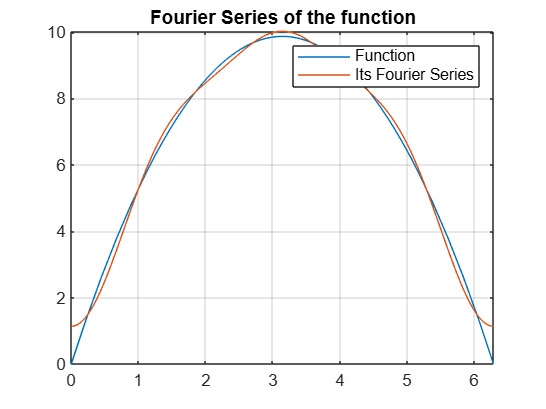

%Visualization by Plotting
fplot(x,y,I)
grid on;
hold on;
fplot(x,F,I)
title('Fourier Series of the function')
legend('Function', 'Its Fourier Series')
hold off

**b) **$\sin \left(x\right)\cos \left(x\right)$** in the interval **$\left\lbrack 1,3\right\rbrack$** .**

clear all
syms x
a=1; %lower limit of the interval
b=3; %upper limit of the interval
I=[a b];
l=(b-a)/2; % the value of l
y = sin(x)*cos(x);
%Construction of Fourier Series
a0 = vpa((1/l)*int(y,x,a,b),3); %Formula for a0
i = 3;
sum1=0;
for n= 1:i
an = (1/l)*int(y*cos((n*pi*x)/l),x,I); %Formula for an
bn = (1/l)*int(y*sin((n*pi*x)/l),x,I); %Formula for bn
sum1 = sum1 + an*cos((n*pi*x)/l) + bn*sin((n*pi*x)/l);
end
F=vpa((a0/2)+sum1,3) %Required Fourier Series

$$F = 0.0388\,\cos\left(6.28\,x\right)-0.066\,\sin\left(9.42\,x\right)-0.234\,\cos\left(3.14\,x\right)-0.0162\,\cos\left(9.42\,x\right)-0.318\,\sin\left(3.14\,x\right)+0.105\,\sin\left(6.28\,x\right)-0.172$$

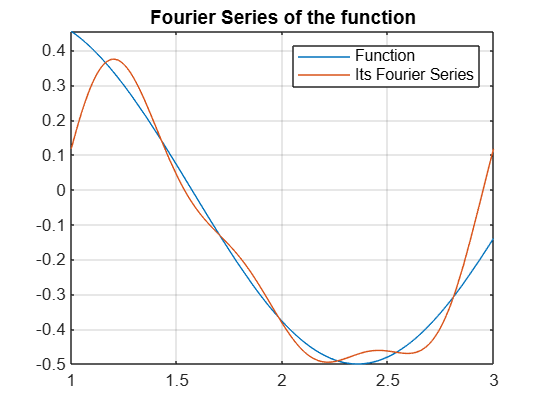

%Visualization by Plotting
fplot(x,y,I)
grid on;
hold on;
fplot(x,F,I)
title('Fourier Series of the function')
legend('Function', 'Its Fourier Series')
hold off

#### Extended activity(OE):

**Write the code to obtain the half range sine and cosine series of the function in **$\left(0,l\right)$ **where** $l=\pi$** .**

clear all
syms x
a=0;
l=pi;
I=[a l];
y = sin(x);
a0 = vpa((2/l)*int(y,x,a,l),3);
i = 3;
sum1=0;
for n= 1:i
an = (2/l)*int(y*cos((n*pi*x)/l),x,I);
sum1 = sum1 + an*cos((n*pi*x)/l);
end
F1=vpa((a0/2)+sum1,3)

$$F1 = 0.637-0.424\,\cos\left(2.0\,x\right)$$

sum2=0;
for n= 1:i
bn = (2/l)*int(y*sin((n*pi*x)/l),x,I);
sum2 = sum2 + bn*sin((n*pi*x)/l);
end
F2=vpa(sum2,3)

$$F2 = 1.0\,\sin\left(x\right)$$

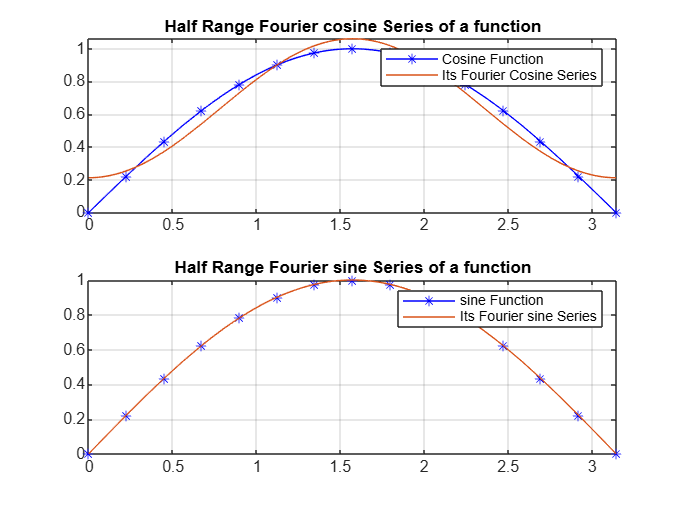

subplot(2,1,1);
fplot(x,y,I,"b-*")
grid on;
hold on;
fplot(x,F1,I)
title('Half Range Fourier cosine Series of a function')
legend('Cosine Function', 'Its Fourier Cosine Series')
hold off
subplot(2,1,2);
fplot(x,y,I,'b-*')
grid on;
hold on;
fplot(x,F2,I)
title('Half Range Fourier sine Series of a function')
legend('sine Function', 'Its Fourier sine Series')
hold off

# `Activity-2: Harmonic Series`

**Explanation****: We find the Harmonic series of a periodic function when the function itself is not known**

**but for a finite number of functional values at some equidistant points are known as follows.**

**For a function of period **$2l$** , the following is a very important observation:**

$2l=\textrm{Nxd}$** ,where N - number of permissible values of **$x$** and **$d$**- common difference.**

**Definition****: The Harmonic series for a a function whose values are given as above is given by:**

$F=\frac{a_0 }{2}+\sum a_n \cos \left(\frac{n\pi x}{l}\right)+\sum b_n \sin \left(\frac{n\pi x}{l}\right)$ **where,**

#### 
$$a_0 =\frac{2}{N}\sum y\;\;\;\;\;,\;\;\;a_n =\frac{2}{N}\sum \textrm{ycos}\left(\frac{n\pi x}{l}\right)\;\;\;\;\;,\;\;\;\;b_n =\frac{2}{N}\sum \textrm{ysin}\left(\frac{n\pi x}{l}\right)$$


#### Question: 

**Compute the harmonic series for**

clear all
X=[0 pi/3 2*pi/3 pi 4*pi/3 5*pi/3]; % Only take the permissible values
y=[7.9 7.2 3.6 0.5 0.9 6.8];%Given data
h=pi/3; %Specify the common difference
N=length(X);
l=(N*h)/2;
a0 = (2/N)*sum(y); %Formula for a0

%Coefficients
for n=1:N
a(n)=(2/N)*sum(y.*cos((n*pi*X)/l)); %Formula for an
b(n)=(2/N)*sum(y.*sin((n*pi*X)/l)); %Formula for bn
end

%Series
syms x
for n=1:N
F=a0/2+sum((a(n)*cos(n*pi*x)/l))+sum((b(n)*sin(n*pi*x)/l));
end
disp(F)

$$\frac{269\,\cos\left(6\,\pi \,x\right)}{30\,\pi }+\frac{4671179330349149\,\sin\left(6\,\pi \,x\right)}{1267650600228229401496703205376\,\pi }+\frac{269}{60}$$

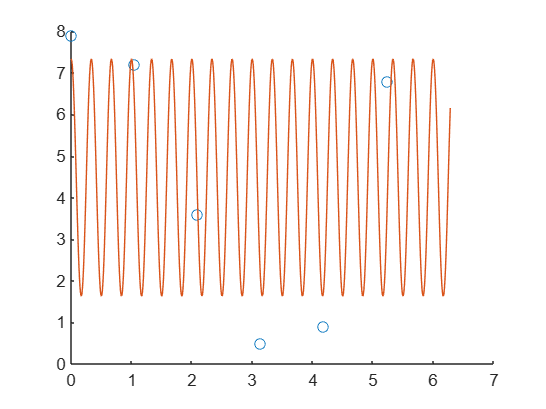

scatter(X,y)
hold on
fplot(x,F,[0,2*pi])
hold off

#### **Excercises:**

**1. Extract the first and second harmonics for the above function by writing the matlab code for it.**

clear
% Initialize coefficients
a1 = 4.0500; 
a2 = -0.2833; 
b1 = 0.8949; 
b2 = -0.6640;

% Display coefficients
fprintf("a1 = %.4f, a2 = %.4f, b1 = %.4f, b2 = %.4f\n", a1, a2, b1, b2);

a1 = 4.0500, a2 = -0.2833, b1 = 0.8949, b2 = -0.6640



% Define parameters
L = 360; % Period length (degrees)
syms x; % Symbolic variable for harmonics

% First harmonic
F1 = a1 * cos((pi * x) / L) + b1 * sin((pi * x) / L);
disp('First Harmonic (F1):');

First Harmonic (F1):


disp(simplify(F1));

$$\frac{81\,\cos\left(\frac{\pi \,x}{360}\right)}{20}+\frac{8949\,\sin\left(\frac{\pi \,x}{360}\right)}{10000}$$


% Second harmonic
F2 = a2 * cos((2 * pi * x) / L) + b2 * sin((2 * pi * x) / L);
disp('Second Harmonic (F2):');

Second Harmonic (F2):


disp(simplify(F2));

$$-\frac{2833\,\cos\left(\frac{\pi \,x}{180}\right)}{10000}-\frac{83\,\sin\left(\frac{\pi \,x}{180}\right)}{125}$$

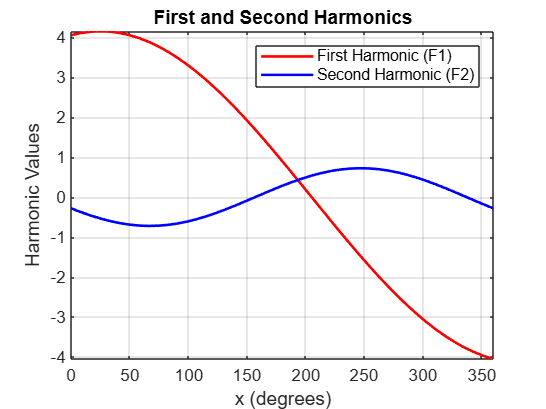


% Plotting the harmonics
fplot(F1, [0, 360], 'r', 'LineWidth', 1.5); % First harmonic
hold on;
fplot(F2, [0, 360], 'b', 'LineWidth', 1.5); % Second harmonic
title('First and Second Harmonics');
xlabel('x (degrees)');
ylabel('Harmonic Values');
legend('First Harmonic (F1)', 'Second Harmonic (F2)');
grid on;
hold off;

**2. Solve for first and second harmonics manually and compare to verify with the above output.**

**3. What is the effect of N( Number of permissible values of x) on the accuracy of the Harmonic series? Explain.**

*Answer*: **Increasing NN (number of permissible values of xx) improves the accuracy of the harmonic series by providing finer resolution and more precise Fourier coefficients . It better captures the function's oscillations and reduces aliasing, leading to a closer match with the original function. However, higher NN increases computational cost, and beyond a certain point, accuracy gains become minimal.**

**4. Obtain the Harmonic series for the following data and hence paste the graphs.**

**a)**

clear all
X=[0 1 2 3 4 5]; % Only take the permissible values
y=[9 18 24 28 26 20];%Given data
h=1; %Specify the common difference
N=length(X);
l=(N*h)/2;
a0 = (2/N)*sum(y); %Formula for a0
%Coefficients
a=zeros;
b=zeros;
for n=1:N
a(n)=(2/N)*sum(y.*cos((n*pi*X)/l)); %Formula for an
b(n)=(2/N)*sum(y.*sin((n*pi*X)/l)); %Formula for bn
end
%Series
syms x
for n=1:N
F=a0/2+sum(a(n)*cos((n*pi*x)/l))+sum(b(n)*sin((n*pi*x)/l));
end
disp(F)

$$\frac{125\,\cos\left(2\,\pi \,x\right)}{3}-\frac{4166325613497621\,\sin\left(2\,\pi \,x\right)}{79228162514264337593543950336}+\frac{125}{6}$$

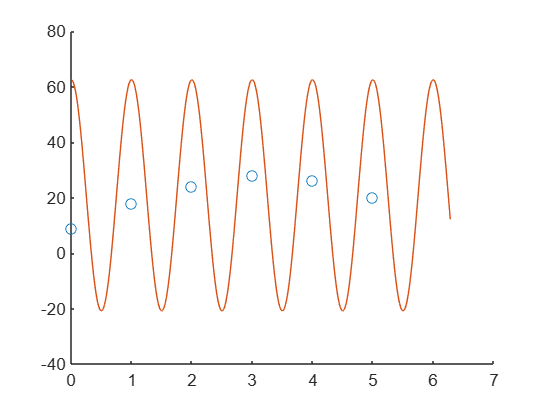

scatter(X,y)
hold on
fplot(x,F,[0,2*pi])
hold off

**b)**

clear all;
X=[0 45 90 135 180 225 270 315]; % Only take the permissible values
y=[2 1.5 1 0.5 0 0.5 1 1.5];%Given data
h=pi/4; %Specify the common difference
N=length(X);
l=(N*h)/2;
a0 = (2/N)*sum(y); %Formula for a0
%Coefficients
a=zeros;
b=zeros;
for n=1:N
a(n)=(2/N)*sum(y.*cos((n*pi*X)/l)); %Formula for an
b(n)=(2/N)*sum(y.*sin((n*pi*X)/l)); %Formula for bn
end
%Series
syms x
for n=1:N
F=a0/2+sum((a(n)*cos((n*pi*x)/l)))+sum((b(n)*sin((n*pi*x)/l)));
end
disp(F)

$$\frac{2397625826333493\,\cos\left(8\,x\right)}{4503599627370496}+\frac{2610734996366095\,\sin\left(8\,x\right)}{36028797018963968}+1$$

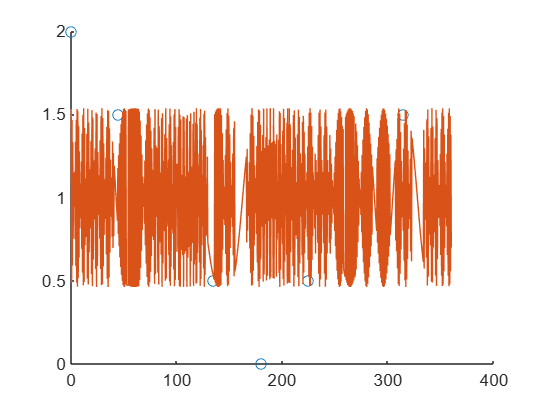

scatter(X,y)
hold on
fplot(x,F,[0,360])
hold off

# `Activity-3: Solving a difference equation using Z-transform`

**Z-transform of a sequence **$u_n$** is:   **$\textrm{Zr}\left(u_n \right)=\sum_n^{\infty } u_n Z^n$** .**

**Example: Compute the Z-transform of **$n\left(1-\left(\frac{1}{n}\right)\right)$** . **  

clc 
clear 
syms n
f=n*(1-(1/n));
Z=ztrans(f) %ztrans() is the inbuilt function in maTlab to obtain the Z transfom 

$$Z = \frac{z}{{\left(z-1\right)}^{2}}-\frac{z}{z-1}$$

**Example: Compute the inverse Z-transform of **$\frac{z}{\left(z-1\right)}$**.**

clc 
clear 
syms z
f=z/(z-1);
un=iztrans(f) %iztrans() is the inbuilt function in maTlab to obtain the inverse Z transfom 

$$un = 1$$

**Z transform can be used to solve difference equations(refer for info: Difreqns MathLibre).**

**Example: You can use the Z-transform to solve difference equations, such as the well-known "Rabbit  Growth" problem. If a pair of rabbits matures in one year, and then produces another pair of rabbits  every year, the rabbit population  at year is described by this difference equation.  **

$y_{n+2} =y_{n+1} +y_n$** with **$y_0 =1$**, **$y_1 =2$**.**

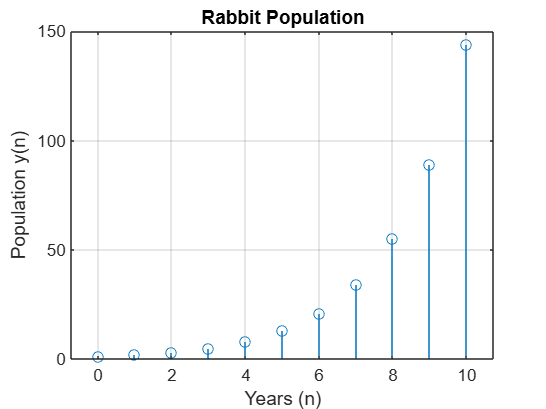

syms y(n) z
assume(n >= 0 & in(n, "integer")); % Specifying n as an integer >= 0

% Define the recurrence relation
f = y(n+2) - y(n+1) - y(n);

% Find the Z-transform of the recurrence relation
fZT = ztrans(f, n, z);

% Replace ztrans(y(n), n, z) with a symbolic variable yZT
syms yZT
fZT = subs(fZT, ztrans(y(n), n, z), yZT);

% Solve for Y(z)
yZT = solve(fZT, yZT);

% Find the inverse Z-transform to get the general solution
ySol = iztrans(yZT, z, n);

% Apply the initial conditions y(0) = 1, y(1) = 2
ySol = subs(ySol, [y(0) y(1)], [1 2]);
ySol = simplify(ySol);

% Generate and plot the stem plot
nValues = 0:10; % Include n = 0 to match the range of the graph
ySolValues = subs(ySol, n, nValues);
ySolValues = double(ySolValues); % Convert symbolic values to numeric
ySolValues = real(ySolValues); % Ensure the values are real numbers

% Clear previous figures to prevent overlays
clf;

% Plot the stem graph
stem(nValues, ySolValues, 'o'); % Include circle markers as shown in the figure
title("Rabbit Population");
xlabel("Years (n)");
ylabel("Population y(n)");
grid on;

#### Excercises: 

**Solve the following difference equations and get a suitable plot (may not be a stemplot) for the sequences obtained and paste the graphs.**

**1) **$y_{n+2} +6y_{n+1} +9y_n =2^n$** with **$y_0 =0,y_1 =0$** .**

syms y(n) z
assume(n >= 0 & in(n, "integer")) % n is a non-negative integer

% Define the difference equation
f = y(n+2) + 6*y(n+1) + 9*y(n) - 2^n;

% Z-transform of the equation
fZT = ztrans(f, n, z);

% Substitute Z-transform of y(n)
syms yZT
fZT = subs(fZT, ztrans(y(n), n, z), yZT);

% Solve for yZT
yZT = solve(fZT, yZT);

% Inverse Z-transform to find the sequence
ySol = iztrans(yZT, z, n);

% Apply initial conditions: y(0) = 0, y(1) = 0
ySol = simplify(subs(ySol, [y(0) y(1)], [0 0]));

% Display the solution
disp("Solution for Problem 1:")

Solution for Problem 1:


disp(ySol)

$$\frac{{\left(-3\right)}^{n}\,n}{15}+\frac{2^{n}}{25}-\frac{{\left(-3\right)}^{n}}{25}$$

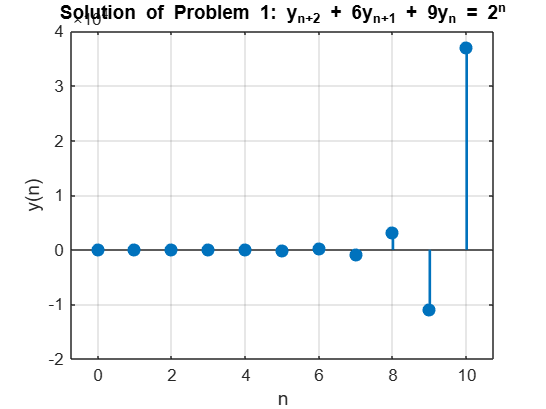

% Compute and plot the solution
nValues = 0:10; % First 10 terms
ySolValues = double(subs(ySol, n, nValues));
stem(nValues, ySolValues, 'filled', 'LineWidth', 1.5);
title("Solution of Problem 1: y_{n+2} + 6y_{n+1} + 9y_n = 2^n");
xlabel("n");
ylabel("y(n)");
grid on;

**2) **$y_{n+2} +5y_{n+1} +6y_n =2$** with **$y_0 =3,y_1 =7$**.**

clear all;
syms y(n) z
assume(n >= 0 & in(n, "integer")) % Specify n as an integer greater than or equal to 0

% Define the recurrence relation
f = y(n + 2) + 5*y(n + 1) + 6*y(n) - 2;

% Perform the Z-transform
fZT = ztrans(f, n, z);

% Substitute the Z-transform of y(n)
syms yZT
fZT = subs(fZT, ztrans(y(n), n, z), yZT);

% Solve for the Z-transform of y(n)
yZT = solve(fZT, yZT);

% Inverse Z-transform to get the solution
ySol = iztrans(yZT, z, n);
ySol = simplify(ySol);

% Apply initial conditions y(0) = 0 and y(1) = 1
ySol = subs(ySol, [y(0), y(1)], [0, 1]);

% Display the simplified solution
disp('Simplified solution:');

Simplified solution:


disp(ySol);

$$\frac{{\left(-2\right)}^{n}}{3}-\frac{{\left(-3\right)}^{n}}{2}+\frac{1}{6}$$

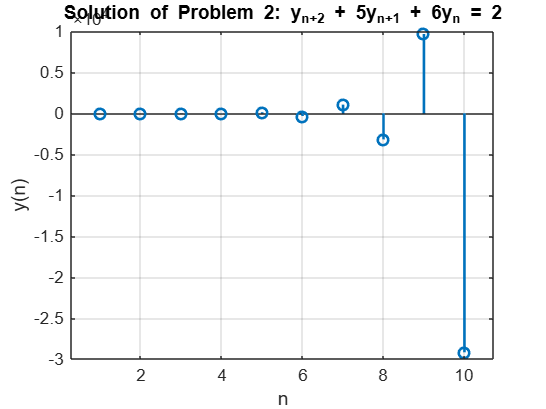


% Generate stem plot
nValues = 1:10; % Define the range of n
ySolValues = subs(ySol, n, nValues); % Substitute n values into solution
ySolValues = double(ySolValues); % Convert symbolic to numeric
ySolValues = real(ySolValues); % Ensure real values for the stem plot

% Plot the solution
figure;
stem(nValues, ySolValues, 'LineWidth', 1.5);
title('Solution of Problem 2: y_{n+2} + 5y_{n+1} + 6y_n = 2');
xlabel('n');
ylabel('y(n)');
grid on;

#### An economic application:  

**We want to investigate the behaviour of price in a market with the demand  and supply functions as follows.**

$D_{t+1} =86-0\ldotp 8P_{t+1}$**  and  **$S_{t+1} =-10+0\ldotp 2P_t$** Assuming that market is cleared (i.e **$D_t =S_t$** ). Form the difference  equation and hence obtain the price at any point of time 't', ie, **$P_t$** if the price initially is **$P_0 =100$**.**

clc;
clear all;
syms P(t) z pZT
assume(t>=0 & in(t,"integer"))
f = P(t+1) + 0.25*P(t) - 120; %since D(t+1)=s(t+1), i.e p at t+1
fZT = ztrans(f,t,z);
fZT = subs(fZT,ztrans(P(t),t,z),pZT);
yZT = solve(fZT,pZT);
pSol = iztrans(yZT,z,t);
pSol = simplify(pSol)

$$pSol = {\left(-\frac{1}{4}\right)}^{t}\,P\left(0\right)-96\,{\left(-\frac{1}{4}\right)}^{t}+96$$

pSol = subs(pSol,P(0),100)% initially(p0) at 100

$$pSol = 4\,{\left(-\frac{1}{4}\right)}^{t}+96$$

**Obtain the stemplot for time **$t=0$** to **$10$** as explained in the first example. Give suitable name for the graph. Paste the graph.**

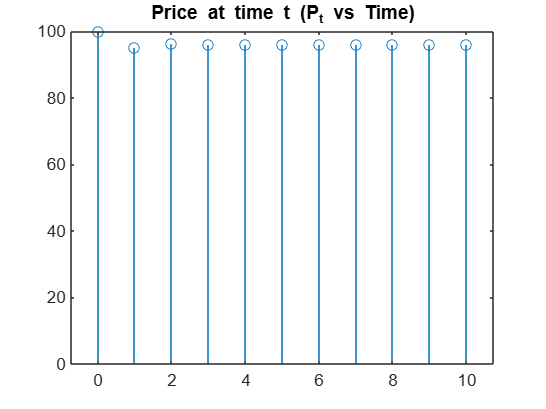

nValues = 0:10;
ySolValues = subs(pSol,t,nValues);ySolValues = double(ySolValues);
ySolValues = real(ySolValues);
stem(nValues,ySolValues);
title('Price at time t (P_t vs Time)');

# `Activity-4: Numerical Solution of One-Dimensional Heat Equation`

**One dimensional heat equation is given by **$u_t =c^2 u_{\textrm{xx}}$**, with initial condition on time and boundary  conditions on the space variable x. Bender-Schmidt method uses the following formula to find the  approximate values of u at the j+1 th time level using the value at jth time level.**

$u_{i,j+1} =\lambda u_{i-1,j} +\left(1-2\lambda \right)u_{i,j} +\lambda u_{i+1,j}$** where **$\lambda =\frac{kc^2 }{h^2 }$** , **$k\;\textrm{and}\;h$** are the step lengths for **$t$** and **$x$** respectively.**

function [x, t, u] = FT_Heat(x0, xm, tn, h, k, c2, f)
    % Spatial and temporal grids
    x = x0:h:xm;                  % Spatial grid
    t = 0:k:tn;                   % Time grid
    Nx = length(x);               % Number of spatial points

Numerical solution of the given equation is : 


    Nt = length(t);               % Number of time points

         0    6.1875   24.0000   51.1875   84.0000  117.1875  144.0000  156.1875  144.0000   96.1875         0
         0   10.8375   27.7500   53.4375   84.1500  114.6375  138.1500  146.4375  129.7500   76.8375         0
         0   13.2675   31.2600   55.4475   84.0600  111.8475  132.0600  136.4475  115.2600   67.2675         0
         0   15.1575   33.7380   57.2175   83.7300  108.8175  125.7300  126.2175  104.5380   59.5575         0
         0   16.5267   35.6976   58.4307   83.1600  105.5475  119.1600  117.3507   95.2176   53.7267         0
         0   17.5844   37.1225   59.2292   82.2233  102.0375  112.9913  109.2212   87.4745   48.8324         0



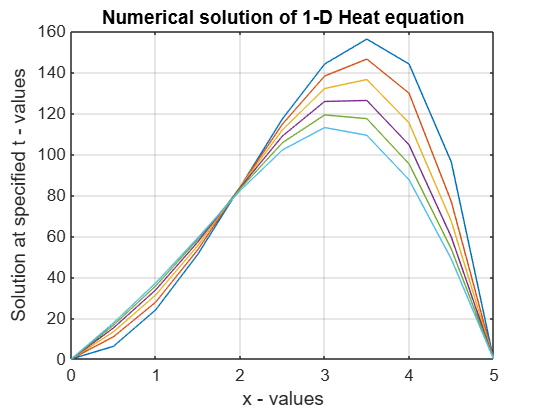

    r = c2 * k / h^2;             % FTCS stability parameter

    % Initialize the solution matrix
    u = zeros(Nt, Nx);


    % Set the initial condition
    u(1, :) = f(x);

    % Time-stepping loop
    for n = 1:Nt-1
        for i = 2:Nx-1
            % FTCS update equation
            u(n+1, i) = u(n, i) + r * (u(n, i-1) - 2*u(n, i) + u(n, i+1));
        end

        % Boundary conditions (Dirichlet)
        u(n+1, 1) = 0;           % u(x0, t) = 0
        u(n+1, Nx) = 0;          % u(xm, t) = 0
    end
end

#### Q. Solve the one-dimensional heat equation.


$$\frac{\partial }{\partial t}u=2\frac{\partial^2 }{\partial x^2 }u$$
  
$$\;\;\;0<x<5,\;\;\;\;t>0,$$


**subject to the conditions:**

             
$$\begin{array}{l}
u\left(0,t\right)=0\;,u\left(5,t\right)=0\;,t\ge 0\;;\\
u\left(x,0\right)=x^2 \left(25-x^2 \right)\;,0\le x\le 5\;\ldotp 
\end{array}$$


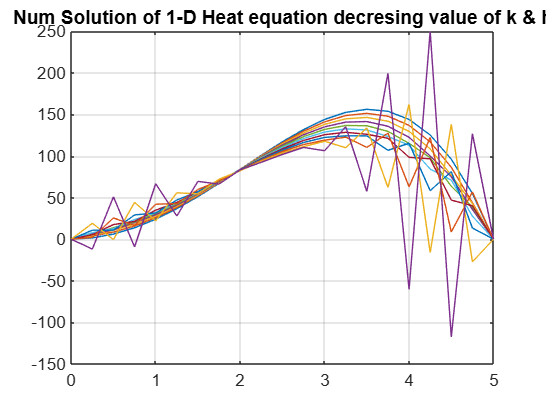

clear all
x0=0; xm = 5; tn = 0.25; h = 0.5; k=0.05; c2=2;
f = @(x) x.^2.*(25-x.^2);
[x,t,u] = FT_Heat(x0,xm,tn,h,k,c2,f);

fprintf('Numerical solution of the given equation is : \n'); 
disp(u);
plot(x,u); 
grid on;
xlabel('x - values');
ylabel('Solution at specified t - values'); 
title('Numerical solution of 1-D Heat equation');

%Defining the function FTCS_Heat
lambda=c2*k/h^2;
x=x0:h:xm; n=length(x); t=0:k:tn; m=length(t); u=zeros(n,m); u(:,1)=f(x);
for j=1:m-1
for i=2:n-1
u(i,j+1)= lambda*u(i-1,j)+(1-2*lambda)*u(i,j)+lambda*u(i+1,j);
end
end

#### Excercise: 

**What is the effect of decreaing the values of **$h$** and **$k$** further on the accuracy of the solution? Observe it by taking **$h=0\ldotp 25$**, **$k=0\ldotp 05$** for the same PDE above. Obtain the output and paste the graph and write your conclusion.**

clear all
x0=0; xm = 5; tn = 0.25; h = 0.25; k=0.025; c2=2;
f = @(x) x.^2.*(25-x.^2);
[x,~,u] = FT_Heat(x0,xm,tn,h,k,c2,f);
plot(x,u); grid on;

Numerical solution of the given equation is : 


title('Num Solution of 1-D Heat equation decresing value of k & h')

         0    0.3090    0.5878    0.8090    0.9511    1.0000    0.9511    0.8090    0.5878    0.3090    0.0000   -0.3090   -0.5878   -0.8090   -0.9511   -1.0000   -0.9511   -0.8090   -0.5878   -0.3090   -0.0000
         0    0.2485    0.4727    0.6506    0.7649    0.8042    0.7649    0.6506    0.4727    0.2485   -0.0000   -0.2485   -0.4727   -0.6506   -0.7649   -0.8042   -0.7649   -0.6506   -0.4727   -0.2485         0
         0    0.0907    0.1725    0.2375    0.2792    0.2936    0.2792    0.2375    0.1725    0.0907    0.0000   -0.0907   -0.1725   -0.2375   -0.2792   -0.2936   -0.2792   -0.2375   -0.1725   -0.0907         0
         0   -0.1026   -0.1952   -0.2686   -0.3158   -0.3321   -0.3158   -0.2686   -0.1952   -0.1026   -0.0000    0.1026    0.1952    0.2686    0.3158    0.3321    0.3158    0.2686    0.1952    0.1026         0
         0   -0.2558   -0.4865   -0.6696   -0.7871   -0.8276   -0.7871   -0.6696   -0.4865   -0.2558    0.0000    0.2558    0.4865    0.6696    0.7871    0.

#### *Conclusion**:*

**By decreasing the spatial step size (h) and time step size (k), the numerical solution becomes more accurate as it reduces truncation errors, ensuring the solution closely approximates the true behavior of the system. Smaller step sizes improve the resolution of the solution by capturing finer details. However, this increased accuracy comes at the cost of higher computational effort, as more grid points and time steps are required, leading to longer computation times and greater resource usage.**

# `Activity-5: Numerical Solution of One-Dimensional Wave Equation`

**One dimensional wave equation is given by **$u_{\textrm{tt}} =c^2 u_{\textrm{xx}}$**, with initial condition on time and boundary**

**conditions on the space variable x. Bender-Schmidt method uses the following formula to find the**

**approximate values of u at the j+1 th time level using the value at jth time level. Let us take an example.**

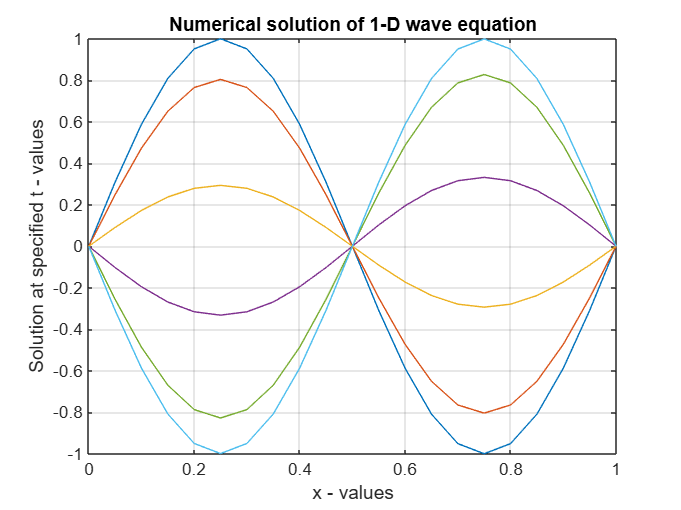

clear all
function [x, t, u] = FT_wave(t0, tm, x0, xn, h, k, c, f, g)
    % Spatial and temporal grids

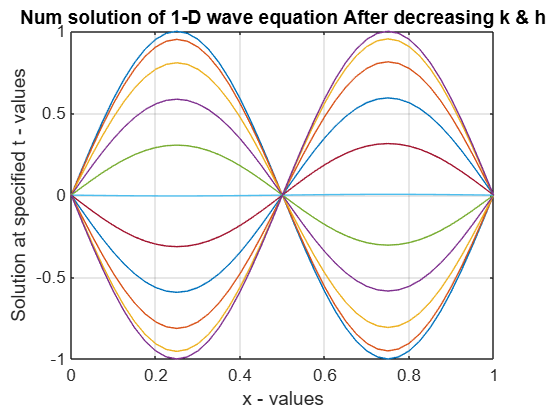

    x = x0:h:xn;                  % Spatial grid
    t = t0:k:tm;                  % Time grid
    Nx = length(x);               % Number of spatial points
    Nt = length(t);               % Number of time points
    r = (c * k / h)^2;            % Courant number squared

    % Initialize the solution matrix
    u = zeros(Nt, Nx);

    % Set initial conditions
    u(1, :) = f(x);               % Initial displacement
    if Nt > 1
        % First time step using initial velocity
        for i = 2:Nx-1
            u(2, i) = u(1, i) + k * g(x(i)) + 0.5 * r * (u(1, i-1) - 2*u(1, i) + u(1, i+1));
        end
        u(2, 1) = 0;              % Boundary condition at x = x0
        u(2, Nx) = 0;             % Boundary condition at x = xn
    end

    % Time-stepping loop for remaining steps
    for n = 2:Nt-1
        for i = 2:Nx-1
            % Wave equation update equation
            u(n+1, i) = 2 * (1 - r) * u(n, i) - u(n-1, i) + r * (u(n, i-1) + u(n, i+1));

        end
        % Boundary conditions
        u(n+1, 1) = 0;            % Boundary condition at x = x0
        u(n+1, Nx) = 0;           % Boundary condition at x = xn
    end
end

#### **Q. Solve the One-Dimensional wave equation:**


$$\frac{\partial^2 }{\partial t^2 }u=4\frac{\partial^2 }{\partial x^2 }u$$
    
$$0<x<1\;,t>0,$$


**subject to the conditions:**

              
$$\begin{array}{l}
u\left(0,t\right)=0,\;\;\;\;u\left(1,t\right)=0\;\;\;,\;\;t\ge 0;\\
u\left(x,0\right)=\sin \left(2\pi x\right)\;,\;u_t \left(x,0\right)=0\;,\;\;\;0\le x\le 1
\end{array}$$


**by defining a function called FT Wave in matlab code and then applying the given conditions.**

clear all
x0=0; xn=1; t0=0; tm=0.5; h=0.05; k=0.1; c=1;
f= @(x) sin(2*pi*x); g = @(x) 0;
[x,t,u] = FT_wave(t0,tm,x0,xn,h,k,c,f,g);
fprintf('Numerical solution of the given equation is : \n'); 
disp(u);
plot(x,u); grid on;
xlabel('x - values');
ylabel('Solution at specified t - values'); 
title('Numerical solution of 1-D wave equation');

%Defining the function FT_Wave
r = c*k/h;
x=x0:h:xn; t=t0:k:tm; n=length(x); m=length(t); u=zeros(n,m); u(:,1)=f(x);
for i=2:n-1
u(i,2)=(1-r^2)*u(i,1)+0.5*(r^2*(u(i-1,1)+u(i+1,1)))+k*g(x(i));
end
for j=2:m-1
for i=2:n-1
u(i,j+1)=2*(1-r^2)*u(i,j)+r^2*(u(i-1,j)+u(i+1,j))-u(i,j-1);
end
end

#### Excercise: 

**What is the effect of decreaing the values of **$h$** and **$k$** further on the accuracy of the solution? Observe it by taking **$h=0\ldotp 05$**, **$k=0\ldotp 05$** for the same PDE above. Obtain the output and paste the graph and write your conclusion.**

clear all
x0=0; xn=1; t0=0; tm=0.5; h=0.025; k=0.05; c=1;
f= @(x) sin(2*pi*x); g = @(x) 0;
[x,t,u] = FT_wave(t0,tm,x0,xn,h,k,c,f,g);
plot(x,u); grid on;
xlabel('x - values');
ylabel('Solution at specified t - values');
title('Num solution of 1-D wave equation After decreasing k & h');

#### Conclusion:

**By decreasing the spatial step size (h) and time step size (k), the solution's accuracy improves due to reduced truncation errors and finer resolution of the wave. Smaller h and k capture the variations in the wave more effectively, minimizing numerical errors. However, this increased accuracy comes at a cost, as it significantly raises computational demands. More grid points and time steps are required, leading to longer computation times and higher memory usage, particularly for complex simulations.**